# Weather Data from ThingSpeak 

## Read historic weather data from ThingSpeak

MATLAB Support for ThingSpeak[](https://www.mathworks.com/matlabcentral/fileexchange/58926-ttplot-tt-) (available via Add On Explorer)

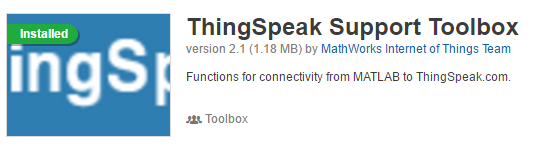

[weather,channelInfo] = thingSpeakRead(12397,...
   'DateRange',[datetime('May 05, 2017'),datetime('May 10, 2017')],...
   'Timeout',20,'OutputFormat','table');  

load tsdata              % data from above call to thingSpeakRead

Create a `timetable` and adjust the properties. Retain channel info in the table metadata.

weather = table2timetable(weather);

weather.Properties.VariableNames = {'WindDir','WindSpeed',...
    'Humidity','TempF','Rain','Pressure','Power','Intensity'};
weather.Properties.UserData = channelInfo;
weather.Properties

ans = struct with fields:
             Description: ''
                UserData: [1×1 struct]
          DimensionNames: {'Timestamps'  'Variables'}
           VariableNames: {'WindDir'  'WindSpeed'  'Humidity'  'TempF'  'Rain'  'Pressure'  'Power'  'Intensity'}
    VariableDescriptions: {}
           VariableUnits: {}
                RowTimes: [7035×1 datetime]


Create a new variable for temperature in Celsius and update the variable units of the `timetable`.

weather.TempC = (5/9)*(weather.TempF - 32);
weather.Properties.VariableUnits({'TempF','TempC'}) = {'F','C'};

Visualize all sensor data using [ttplot from the File Exchange](https://www.mathworks.com/matlabcentral/fileexchange/58926-ttplot-tt-) (available via Add On Explorer)

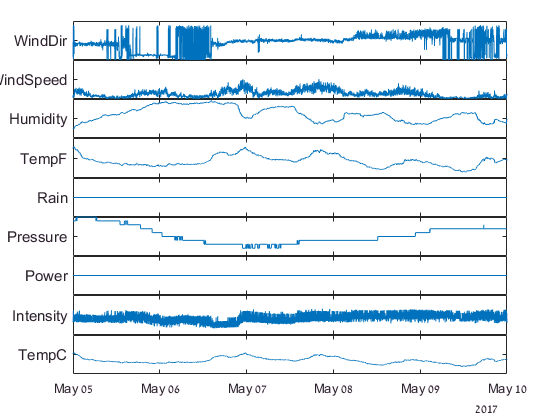

ttplot(weather) % Plot data from a timetable

## Missing data

Determine the number of missing values in each variable.

numMissing = sum(ismissing(weather))

numMissing =      0     0     0     0     0     0     0     0     0


Fill missing values for temperatures and humidity using linear interpolation.

weather = fillmissing(weather,'linear',...
    'DataVariables',{'Humidity','TempF','TempC'});

Retain the fill method in the `timetabl``e` properties.

weather.Properties.VariableDescriptions(...
    {'Humidity','TempF','TempC'}) = {'lin_interp'};
weather.Properties

ans = struct with fields:
             Description: ''
                UserData: [1×1 struct]
          DimensionNames: {'Timestamps'  'Variables'}
           VariableNames: {'WindDir'  'WindSpeed'  'Humidity'  'TempF'  'Rain'  'Pressure'  'Power'  'Intensity'  'TempC'}
    VariableDescriptions: {''  ''  'lin_interp'  'lin_interp'  ''  ''  ''  ''  'lin_interp'}
           VariableUnits: {''  ''  ''  'F'  ''  ''  ''  ''  'C'}
                RowTimes: [7035×1 datetime]
